# **Open-Ended Experiments**

## **Simpson's 3/8th rule of integration:**

function[I]=simpson38(y,a,b,n)
if mod(n,3)~=0
disp("n must be multiple of 3");
return
end
h=(b-a)/n;
if numel(y)>1
I=(h*3/8)*(y(1)+y(n+1)+3*(sum(y(2:3:n-1))+sum(y(3:3:n))+2*sum(y(4:3:n-2))));
else
x=a:h:b;
I=(3*h/8)*(y(a)+y(b)+3*(sum(y(x(2:3:n-1)))+sum(y(x(3:3:n))))+2*sum(y(x(4:3:n-2))));
end
end

### Questions:

Q1. $\int_2^8 \frac{1}{\log_{10} \left(x\right)}\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) 1./log10(x);
a=2;
b=8;
n=6;
I1=simpson38(y,a,b,n)

I1 = 9.7374

Q2. $\int_0^{0\ldotp 3} \sqrt{1-8x^3 }\textrm{dx}$ by taking 7 ordinate points i.e 6 equal sub-intervals.

y=@(x) sqrt(1-8*x.^3);
a=0;
b=0.3;
n=6;
I2=simpson38(y,a,b,n)

I2 = 0.2916

Q3. $\int_0^{0\ldotp 6} e^{{-x}^2 }$ by taking 6 equal sub-intervals.

y=@(x)exp(-x.^2);
a=0;
b=0.6;
n=6;
I3=simpson38(y,a,b,n)

I3 = 0.5352

 Q4. $\int_4^2 \log \left(x\right)\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) ((log(x)));
a=4;
b=5.2;
n=6;
I4=simpson38(y,a,b,n)

I4 = 1.8278

Q5. $\int_1^3 e^{\frac{1}{x}} \;\textrm{dx}$ by taking 6 equal sub-intervals.

y=@(x) exp(1./x);
a=1;
b=3;
n=6;
I5=simpson38(y,a,b,n)

I5 = 3.5249

## RK's 2nd Order Differential method:

### Questions:

Q1. Solve the differential equation $\frac{d^2 y}{dx^2 }-x^2 \frac{\textrm{dy}}{\textrm{dx}}-2xy=1$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=0$ and compute $y\left(0\ldotp 1\right)$ and $y\left(0\ldotp 2\right)$ .

clearvars
%initial condition and inputs
x0=0;
y0=1;
z0=0;
h=0.1;
xn=1;
f=@(x,y,z) z;
g=@(x,y,z) 1+(x^2*z+2*x*y);
x=x0:h:xn; %range
n=length(x)-1; %length of x
y(1)=y0; %initialization
z(1)=z0;
for i=1:n
 k1=h*f(x(i),y(i),z(i));
 l1=h*g(x(i),y(i),z(i));
 k2=h*f(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 l2=h*g(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 k3=h*f(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 l3=h*g(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 k4=h*f(x(i)+h,y(i)+k3,z(i)+l3);
 l4=h*g(x(i)+h,y(i)+k3,z(i)+l3);
 y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
 z(i+1)=z(i)+(l1+2*l2+2*l3+l4)/6;
end
disp(y(1:end))

    1.0000    1.0053    1.0227    1.0543    1.1026    1.1707    1.2626    1.3837    1.5411    1.7449    2.0093



disp('The value of y at x=0.1 is');

The value of y at x=0.1 is


disp(y(2))

    1.0053



disp('The value of z at x=0.2 is');

The value of z at x=0.2 is


disp(z(2))

    0.1101



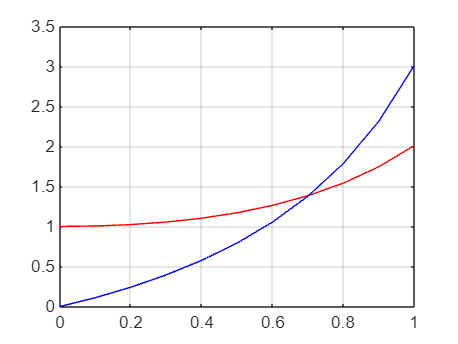

plot(x,y,'r',x,z,'b')
grid on

Q2. Compute $y$ at $x=0\ldotp 1$given $\frac{d^2 y}{dx^2 }=x^3 \left(y+\frac{\textrm{dy}}{\textrm{dx}}\right)$ with $y\left(0\right)=1$,$y^{\prime } \left(0\right)=0\ldotp 5$ .

clearvars
%initial condition and inputs
x0=0;
y0=1;
z0=0.5;
h=0.1;
xn=1;
f=@(x,y,z) z;
g=@(x,y,z) x^3*(y+z);
x=x0:h:xn; %range
n=length(x)-1; %length of x
y(1)=y0; %initialization
z(1)=z0;
for i=1:n
 k1=h*f(x(i),y(i),z(i));
 l1=h*g(x(i),y(i),z(i));
 k2=h*f(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 l2=h*g(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 k3=h*f(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 l3=h*g(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 k4=h*f(x(i)+h,y(i)+k3,z(i)+l3);
 l4=h*g(x(i)+h,y(i)+k3,z(i)+l3);
 y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
 z(i+1)=z(i)+(l1+2*l2+2*l3+l4)/6;
end
disp(y(1:end))

    1.0000    1.0500    1.1000    1.1502    1.2008    1.2526    1.3067    1.3648    1.4299    1.5060    1.5994



disp('The value of y at x=0.1 is');

The value of y at x=0.1 is


disp(y(2))

    1.0500



disp('The value of z at x=0.1 is');

The value of z at x=0.1 is


disp(z(2))

    0.5000



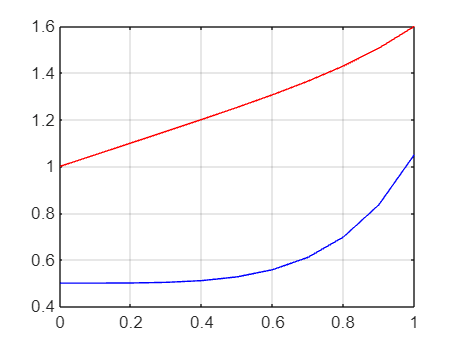

plot(x,y,'r',x,z,'b')
grid on

Q3. Solve $\frac{d^2 y}{dx^2 }=x{\left(\frac{\textrm{dy}}{\textrm{dx}}\right)}^2 -y^2 =0$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=0$and find the value of $y$ at $x=0\ldotp 2$ .

clearvars
%initial condition and inputs
x0=0;
y0=1;
z0=0;
h=0.2;
xn=1;
f=@(x,y,z) z;
g=@(x,y,z) x*z^2-y^2;
x=x0:h:xn; %range
n=length(x)-1; %length of x
y(1)=y0; %initialization
z(1)=z0;
for i=1:n
 k1=h*f(x(i),y(i),z(i));
 l1=h*g(x(i),y(i),z(i));
 k2=h*f(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 l2=h*g(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 k3=h*f(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 l3=h*g(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 k4=h*f(x(i)+h,y(i)+k3,z(i)+l3);
 l4=h*g(x(i)+h,y(i)+k3,z(i)+l3);
 y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
 z(i+1)=z(i)+(l1+2*l2+2*l3+l4)/6;
end
disp(y(1:end))

    1.0000    0.9801    0.9226    0.8335    0.7230    0.6025



disp('The value of y at x=0.2 is');

The value of y at x=0.2 is


disp(y(2))

    0.9801



disp('The value of z at x=0.2 is');

The value of z at x=0.2 is


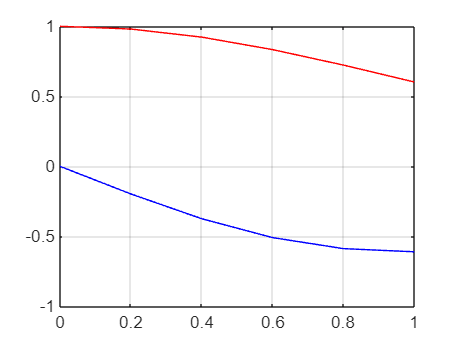

plot(x,y,'r',x,z,'b')
grid on

Q4. Solve $\frac{d^2 y}{dx^2 }=2\frac{\textrm{dy}}{\textrm{dx}}-y$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=2$and find the value of $y$ at $x=0\ldotp 1$ .

clearvars
x0=0;
y0=1;
z0=2;
h=0.1;
xn=1;
f=@(x,y,z) z;
g=@(x,y,z) 2*z-y;
%range
x=x0:h:xn;
%length of x
n=length(x)-1;
%initialization
y(1)=y0;
z(1)=z0;
for i=1:n
 k1=h*f(x(i),y(i),z(i));
 l1=h*g(x(i),y(i),z(i));
 k2=h*f(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 l2=h*g(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 k3=h*f(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 l3=h*g(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 k4=h*f(x(i)+h,y(i)+k3,z(i)+l3);
 l4=h*g(x(i)+h,y(i)+k3,z(i)+l3);
 y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
 z(i+1)=z(i)+(l1+2*l2+2*l3+l4)/6;
end
disp(y(1:end))

    1.0000    1.2157    1.4657    1.7548    2.0886    2.4731    2.9154    3.4234    4.0060    4.6732    5.4365



disp('The value of y at x=0.1 is');

The value of y at x=0.1 is


disp(y(2))

    1.2157



disp('The value of z at x=0.1 is');

The value of z at x=0.1 is


disp(z(2))

    2.3209



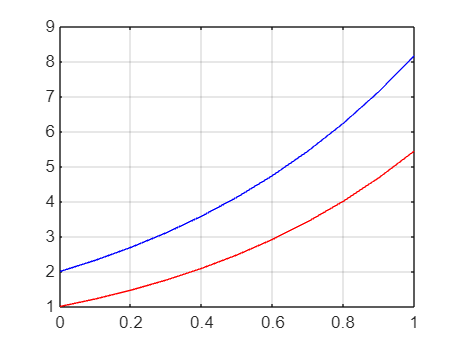

%ploting of graph
plot(x,y,'r',x,z,'b')
grid on

Q5. Solve $\frac{d^2 y}{dx^2 }+\frac{\textrm{dy}}{\textrm{dx}}-6y=0$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=1$and find the value of $y$ at $x=0\ldotp 2\;$.

clearvars
x0=0;
y0=1;
z0=1;
h=0.2;
xn=1;
f=@(x,y,z) z;
g=@(x,y,z) 6*y-z;
x=x0:h:xn; %range
n=length(x)-1; %length of x
y(1)=y0; %initialization
z(1)=z0;
for i=1:n
 k1=h*f(x(i),y(i),z(i));
 l1=h*g(x(i),y(i),z(i));
 k2=h*f(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 l2=h*g(x(i)+h/2,y(i)+k1/2,z(i)+l1/2);
 k3=h*f(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 l3=h*g(x(i)+h/2,y(i)+k2/2,z(i)+l2/2);
 k4=h*f(x(i)+h,y(i)+k3,z(i)+l3);
 l4=h*g(x(i)+h,y(i)+k3,z(i)+l3);
 y(i+1)=y(i)+(k1+2*k2+2*k3+k4)/6;
 z(i+1)=z(i)+(l1+2*l2+2*l3+l4)/6;
end
disp(y(1:end))

    1.0000    1.3033    1.8406    2.6888    3.9797    5.9194



disp('The value of y at x=0.2 is');

The value of y at x=0.2 is


disp(y(2))

    1.3033



disp('The value of z at x=0.2 is');

The value of z at x=0.2 is


disp(z(2))

    2.0571



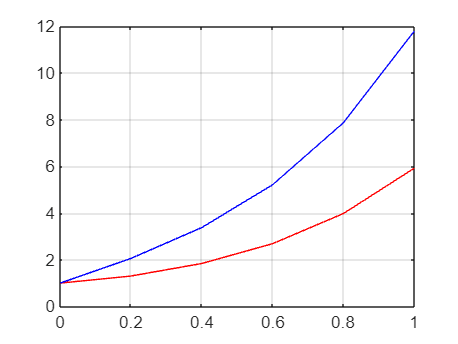

plot(x,y,'r',x,z,'b')
grid on